% main.m
%
% Matlab script that calls all the functions for computing the optimal cost
% and policy of the given problem.
%
% Dynamic Programming and Optimal Control
% Fall 2020
% Programming Exercise
%
% --
% ETH Zurich
% Institute for Dynamic Systems and Control
%
% --

## Clear workspace and command window

clear all;
close all;
clc;

## Options

[M, N]

mapSize = [15, 20];
% Set to true to generate a random map of size mapSize, else set to false 
% to load the pre-exsisting example map
generateRandomWorld = true;

% Plotting options
global PLOT_POLICY PLOT_COST
PLOT_POLICY = true;
PLOT_COST = true;

## Global problem parameters

IMPORTANT: Do not add or remove any global parameter in main.m

global GAMMA R Nc P_WIND
GAMMA  = 0.2; % Shooter gamma factor
R = 2; % Shooter range
Nc = 10; % Time steps required to bring drone to base when it crashes
P_WIND = 0.1; % Gust of wind probability

% IDs of elements in the map matrix
global FREE TREE SHOOTER PICK_UP DROP_OFF BASE 
FREE = 0;
TREE = 1;
SHOOTER = 2;
PICK_UP = 3;
DROP_OFF = 4;
BASE = 5;

% Index of each action in the P and G matrices. Use this ordering
global NORTH SOUTH EAST WEST HOVER
NORTH  = 2;
SOUTH = 5;
EAST = 3;
WEST = 4;
HOVER = 1;

## Generate map

map(m,n) represents the cell at indices (m,n) according to the axes specified in the PDF.

disp('Generate map');

Generate map


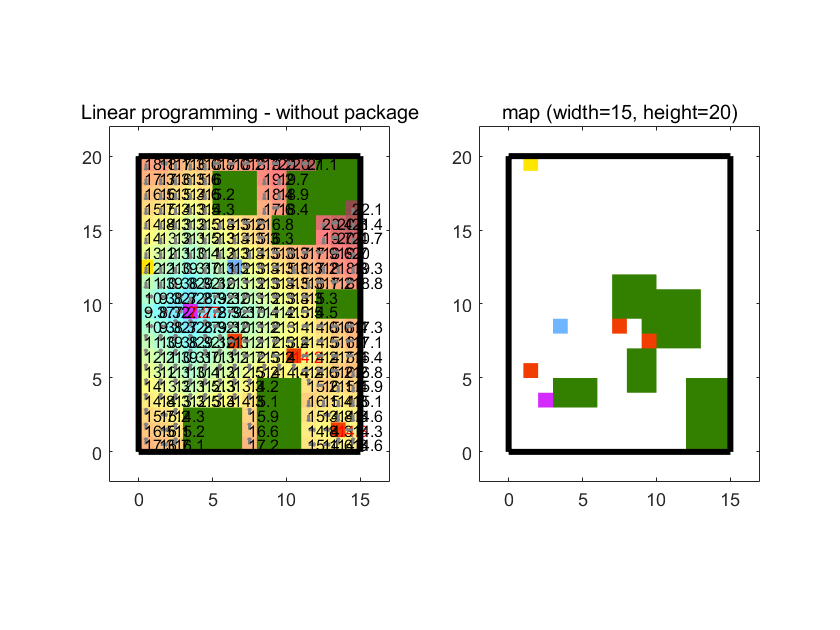

if generateRandomWorld
	[map] = GenerateWorld(mapSize(1), mapSize(2));
else
    % We can load a pre-generated map.
    load('exampleWorld.mat');
end
MakePlots(map);

## Generate state space

disp('Generate state space');

Generate state space


% Generate a (K x 3)-matrix 'stateSpace', where each accessible cell is
% represented by two rows (with and without carrying a package).
stateSpace = [];
for m = 1 : size(map, 1)
    for n = 1 : size(map, 2)
        if map(m, n) ~= TREE
            stateSpace = [stateSpace;
                          m, n, 0;
                          m, n, 1];
        end
    end
end
% State space size
global K
K=size(stateSpace,1);

## Set the following to true as you progress with the files

transitionProbabilitiesImplemented = true;
stageCostsImplemented = true;
valueIterationImplemented = true; 
policyIterationImplemented = true;
linearProgrammingImplemented = true;

## Compute the terminal state index

global TERMINAL_STATE_INDEX
if transitionProbabilitiesImplemented
    % TODO: Question a)
    TERMINAL_STATE_INDEX = ComputeTerminalStateIndex(stateSpace, map);
end

## Compute transition probabilities

if transitionProbabilitiesImplemented
    disp('Compute transition probabilities');
    % Compute the transition probabilities between all states in the
    % state space for all control inputs.
    % The transition probability matrix has the dimension (K x K x L), i.e.
    % the entry P(i, j, l) representes the transition probability from state i
    % to state j if control input l is applied.
    
    % TODO: Question b)
    P = ComputeTransitionProbabilities(stateSpace, map);
end

Compute transition probabilities


## Compute stage costs

if stageCostsImplemented 
    disp('Compute stage costs');
    % Compute the stage costs for all states in the state space for all
    % control inputs.
    % The stage cost matrix has the dimension (K x L), i.e. the entry G(i, l)
    % represents the cost if we are in state i and apply control input l.
    
    % TODO: Question c)
    G = ComputeStageCosts(stateSpace, map);
end

Compute stage costs


G

G =     1.2250       Inf    1.2250       Inf    1.4500
    1.2250       Inf    1.2250       Inf    1.4500
    1.2250    1.4500    1.0000       Inf    1.2250
    1.2250    1.4500    1.0000       Inf    1.2250
    1.2550    1.2250    1.0150       Inf    1.2250
    1.2550    1.2250    1.0150       Inf    1.2250
    1.8100    1.2250    1.5625       Inf    1.2550
    1.8100    1.2250    1.5625       Inf    1.2550
    2.1100    1.2550    1.9000       Inf    1.8100
    2.1100    1.2550    1.9000       Inf    1.8100


## Solve stochastic shortest path problem

Solve the stochastic shortest path problem by Value Iteration, Policy Iteration, and Linear Programming

if valueIterationImplemented
    disp('Solve stochastic shortest path problem with Value Iteration');
    
    % TODO: Question d)
    [ J_opt_vi, u_opt_ind_vi ] = ValueIteration(P, G);
    
    if size(J_opt_vi,1)~=K || size(u_opt_ind_vi,1)~=K
        disp('[ERROR] the size of J and u must be K')
    end
end

Solve stochastic shortest path problem with Value Iteration


J_opt_vi

J_opt_vi =    12.3394
   11.9784
   11.4240
   11.0462
   10.4868
   10.0911
    9.5223
    9.1118
   10.4484
    8.0438


if policyIterationImplemented
    disp('Solve stochastic shortest path problem with Policy Iteration');
    
    % TODO: Question d)
    [ J_opt_pi, u_opt_ind_pi ] = PolicyIteration(P, G);
    
    if size(J_opt_pi,1)~=K || size(u_opt_ind_pi,1)~=K
        disp('[ERROR] the size of J and u must be K')
    end
end

Solve stochastic shortest path problem with Policy Iteration


J_opt_pi

J_opt_pi =    12.3394
   11.9784
   11.4240
   11.0462
   10.4868
   10.0911
    9.5223
    9.1118
   10.4484
    8.0438


if linearProgrammingImplemented
    disp('Solve stochastic shortest path problem with Linear Programming');
    
    % TODO: Question d)
    [ J_opt_lp, u_opt_ind_lp ] = LinearProgramming(P, G);
    
    if size(J_opt_lp,1)~=K || size(u_opt_ind_lp,1)~=K
        disp('[ERROR] the size of J and u must be K')
    end
end

Solve stochastic shortest path problem with Linear Programming


J_opt_lp

J_opt_lp =    12.3394
   11.9784
   11.4240
   11.0462
   10.4868
   10.0911
    9.5223
    9.1118
   10.4484
    8.0438


## Plot results

disp('Plot results');

Plot results


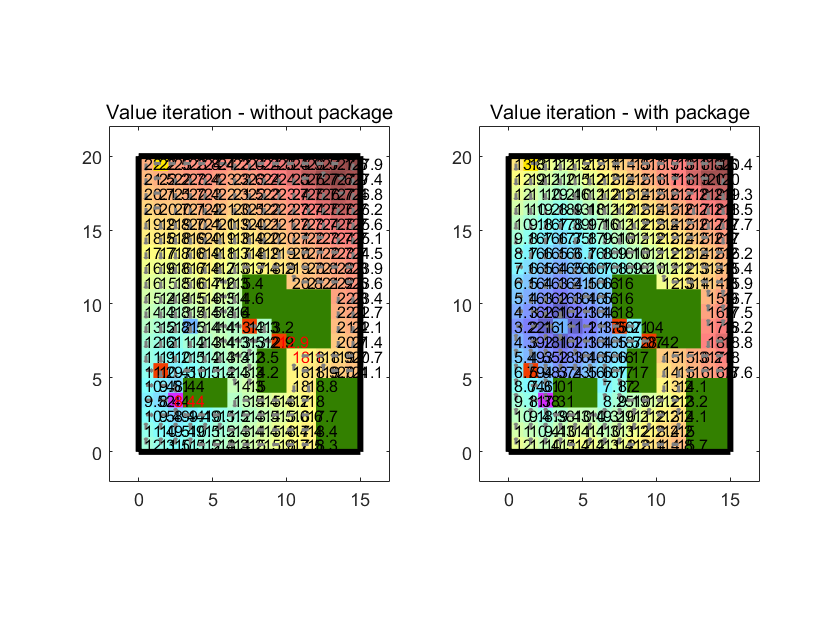

if valueIterationImplemented
    MakePlots(map, stateSpace, J_opt_vi, u_opt_ind_vi, 'Value iteration');
end

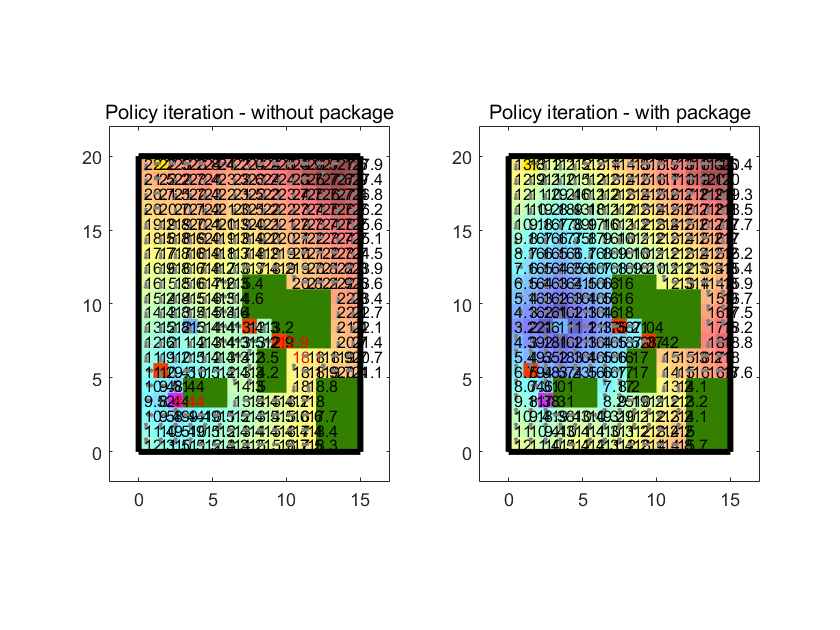

if policyIterationImplemented
    MakePlots(map, stateSpace, J_opt_pi, u_opt_ind_pi, 'Policy iteration');
end

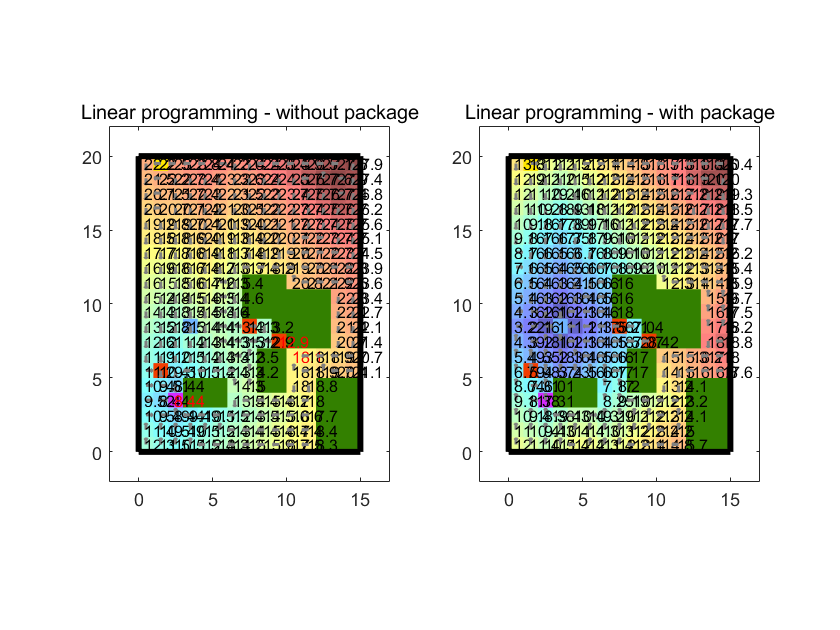

if linearProgrammingImplemented
    MakePlots(map, stateSpace, J_opt_lp, u_opt_ind_lp, 'Linear programming');
end

## Terminated

disp('Terminated');